# Gyakorlat1

Vektor definiálás elemenként.

% v=[1 5 7]

Új elemek hozzáfűzése

% w= [2 v 9]
% u= [ v w ]

Bizonyos indexű elemekre való hivatkozás

% w(1) % első eleme
% w(end) % utolsó elem
% w(1:3) % első 3 eleme

Második és negyedik elem

% w([2 4])

páros indexű elemek

% w(2:2:end)
% %elsőelem:lépésköz:felsőhatár

háromnál nagyobb elemek

% w(w>3)

háromnál nagyobb elemek száma

% sum(w>3)

Mátrixok

% s1=[1 4 8]; s2=[4 7 11];
% M=[s1;s2]

Második sor, második oszlop elem

% M(2,2)

Második sor

% M(2,:)

Cell (lista)

% l={1 'szia' [1 2 3 ; 4 5 6]}

Hivatkozás lista beli elemre

% l{3}

Structure (nevesitett lista)

% s = struct('X',3,'Y',[2 3]);
% s.X

Adattábla (table)

% x = [1 2 3]'; % ' transzponálás
% y = (4:6)';
% t=table(x,y)
% t(:,2)

Eloszlások

% % N(10,3^2)
% % F(5) eloszlásfv.
% normcdf(5,10,3)
% % f(5) sűrűségfüggvény
% normpdf(5,10,3)
% % 0.25 kvantilis
% norminv(0.25,10,3)
% % várható érték és szórásnégyzet
% [m v] = normstat(10,3)
% normrnd(10,3,[3 3])

ábrázoljuk a sűrűségfüggvényt

a [5,15] intervallumon

% x=linspace(5,15)
% y = normpdf(x,10,3)
% figure
% plot(x,y)

ugyanerre az ábárra N(10,2) sfv.

% hold on;
z=normpdf(x,10,2)

z =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


% plot(x,z)
% legend('N(10,3^2)','N(10,2^2')
% 
% hold off

Binom(10,0.5)

% x= 0:10;
% y=binopdf(x,10,0.5) %valószínüségek
% plot(x,y,'*')

Adatok behivatkozása

ustemp=readtable('UStemps.txt')

ustemp = 56×4 table
            City             JanTemp    Lat     Long 
    _____________________    _______    ____    _____

    {'Mobile, AL'       }      44       31.2     88.5
    {'Montgomery, AL'   }      38       32.9     86.8
    {'Phoenix, AZ'      }      35       33.6    112.5
    {'Little Rock, AR'  }      31       35.4     92.8
    {'Los Angeles, CA'  }      47       34.3    118.7
    {'San Francisco, CA'}      42       38.4      123
    {'Denver, CO'       }      15       40.7    105.3
    {'New Haven, CT'    }      22       41.7     73.4
    {'Wilmington, DE'   }      26       40.5     76.3
    {'Washington, DC'   }      30       39.7     77.5
    {'Jacksonville, FL' }      45         31     82.3
    {'Key West, FL'     }      65         25       82
    {'Miami, FL'        }      58       26.3     80.7
    {'Atlanta, GA'      }      37

ustemp.City

ans = 56×1 cell array
    {'Mobile, AL'       }
    {'Montgomery, AL'   }
    {'Phoenix, AZ'      }
    {'Little Rock, AR'  }
    {'Los Angeles, CA'  }
    {'San Francisco, CA'}
    {'Denver, CO'       }
    {'New Haven, CT'    }
    {'Wilmington, DE'   }
    {'Washington, DC'   }
    {'Jacksonville, FL' }
    {'Key West, FL'     }
    {'Miami, FL'        }
    {'Atlanta, GA'      }
    {'Boise, ID'        }
    {'Chicago, IL'      }
    {'Indianapolis, IN' }
    {'Des Moines, IA'   }
    {'Wichita, KS'      }
    {'Louisville, KY'   }
    {'New Orleans, LA'  }
    {'Portland, ME'     }
    {'Baltimore, MD'    }
    {'Boston, MA'       }
    {'Detroit, MI'      }
    {'Minneapolis, MN'  }
    {'St. Louis, MO'    }
    {'Helena, MT'       }
    {'Omaha, NE'        }
    {'Concord, NH'      }


Fahrenheitbő celciusba

ustemp.JanTemp

ans =     44
    38
    35
    31
    47
    42
    15
    22
    26
    30


C=(ustemp.JanTemp-32)/1.8

C =     6.6667
    3.3333
    1.6667
   -0.5556
    8.3333
    5.5556
   -9.4444
   -5.5556
   -3.3333
   -1.1111


comparison=table(ustemp.JanTemp,C)

comparison = 56×2 table
    Var1      Var2  
    ____    ________

     44       6.6667
     38       3.3333
     35       1.6667
     31     -0.55556
     47       8.3333
     42       5.5556
     15      -9.4444
     22      -5.5556
     26      -3.3333
     30      -1.1111
     45       7.2222
     65       18.333
     58       14.444
     37       2.7778
     22      -5.5556
     19      -7.2222


mean(C) %Átlag

ans = -3.0456

std(C) %Szórás

ans = 7.4332

median(C) % medián

ans = -4.1667

quantile(C,[.25,.75])

ans =    -7.5000    0.8333


ustemp.City(C==min(C))

ans = 1×1 cell array
    {'Bismarck, ND'}


ustemp.Celcius=C

ustemp = 56×5 table
            City             JanTemp    Lat     Long     Celcius 
    _____________________    _______    ____    _____    ________

    {'Mobile, AL'       }      44       31.2     88.5      6.6667
    {'Montgomery, AL'   }      38       32.9     86.8      3.3333
    {'Phoenix, AZ'      }      35       33.6    112.5      1.6667
    {'Little Rock, AR'  }      31       35.4     92.8    -0.55556
    {'Los Angeles, CA'  }      47       34.3    118.7      8.3333
    {'San Francisco, CA'}      42       38.4      123      5.5556
    {'Denver, CO'       }      15       40.7    105.3     -9.4444
    {'New Haven, CT'    }      22       41.7     73.4     -5.5556
    {'Wilmington, DE'   }      26       40.5     76.3     -3.3333
    {'Washington, DC'   }      30       39.7     77.5     -1.1111
    {'Jacksonvill

ind=find(C==min(C))

ind = 37

ustemp(ind,:)

ans = 1×5 table
          City          JanTemp    Lat     Long    Celcius
    ________________    _______    ____    ____    _______

    {'Bismarck, ND'}       0       47.1    101     -17.778


Hisztogram-gyakorisági

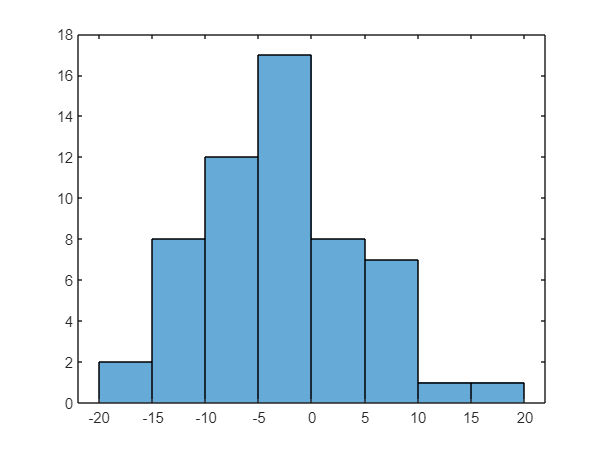

histogram(ustemp.Celcius)

Sűrűségi hisztogram

histogram(ustemp.Celcius,'Normalization','pdf')

illesszünk normális sfv-t.

%megbecsüljük a normális eloszlást és paramétereit
[m s]=normfit(ustemp.Celcius)

m = -3.0456

s = 7.4332

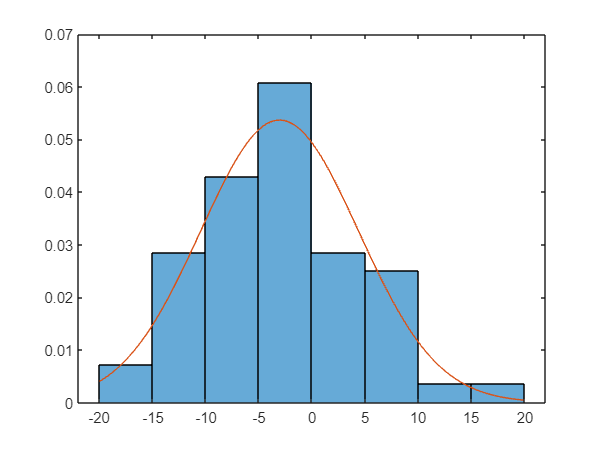

hold on
x=linspace(-20,20);
y=normpdf(x,m,s);
plot(x,y)
hold off

dobozábra

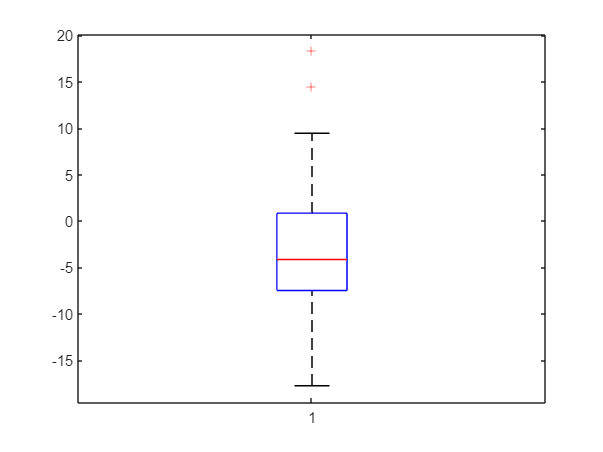

boxplot(ustemp.Celcius)

szélességi fokok alapján osszuk 2felé a városokat

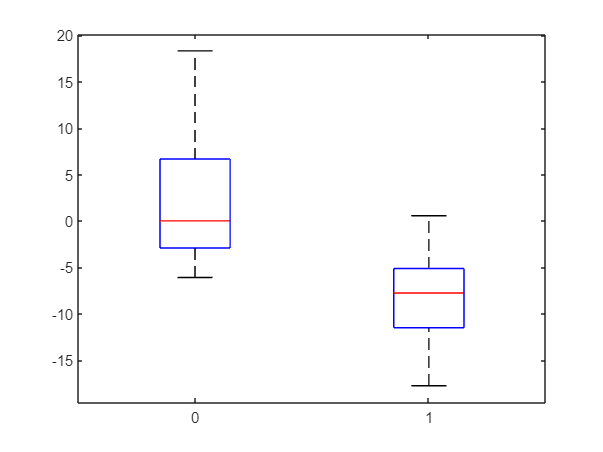

m = median(ustemp.Lat);
osztaly= m<ustemp.Lat;

boxplot(ustemp.Celcius,osztaly)

hosszusági alapján

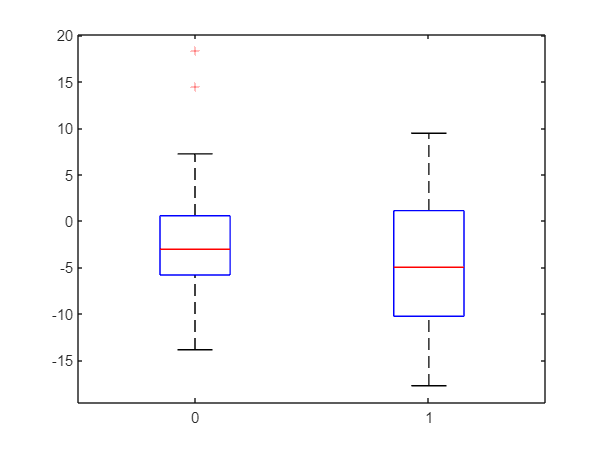

m = median(ustemp.Long);
osztaly= m<ustemp.Long;

boxplot(ustemp.Celcius,osztaly)

ecdf()